clear; clc; close all;

R = 10;
L = 0.01;
C = 1e-6;
s = tf('s');
G = 1 / (L*C*s^2 + R*C*s + 1);

% 加入超前校正器 C_lead
% 目标PM=60°，原PM=8.11°，需补偿约57°
a = (1 + sind(57)) / (1 - sind(57));
w_c = 14286;
z = w_c / sqrt(a);
p = w_c * sqrt(a);
K = sqrt(a);

C_lead = K * (s + z) / (s +p);
G_open = C_lead * G;

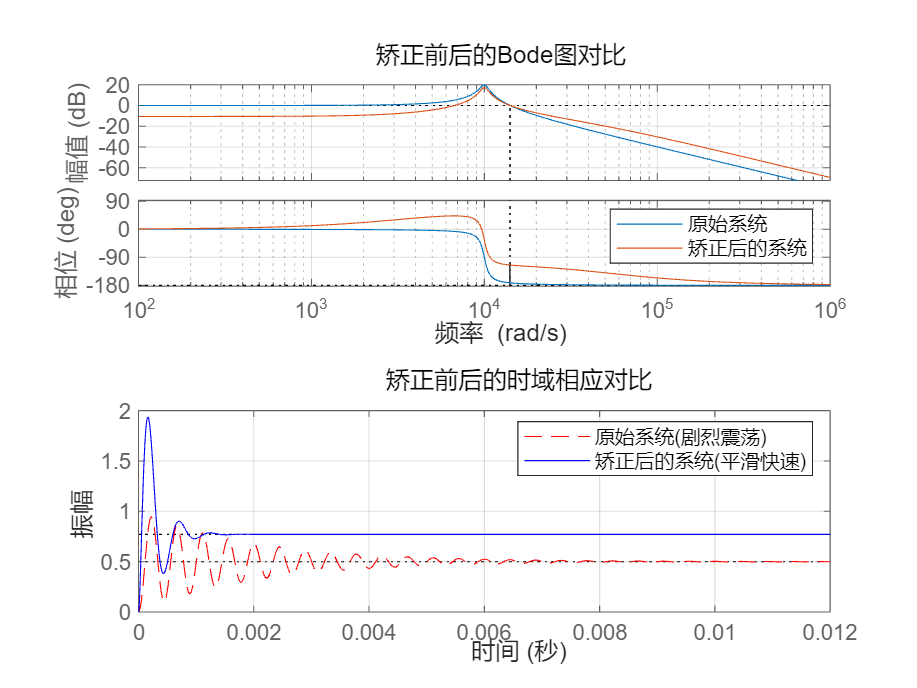

figure;
subplot(2,1,1);
margin(G);hold on;
margin(G_open); 
legend("原始系统", "矫正后的系统");
title("矫正前后的Bode图对比");
grid on; hold off;

T_old = feedback(G, 1);
T_new = feedback(G_open, 1) / (K * z / p);

subplot(2,1,2);
step(T_old, 'r--', T_new, 'b-');
legend("原始系统(剧烈震荡)", "矫正后的系统(平滑快速)");
title("矫正前后的时域相应对比");
grid on; 

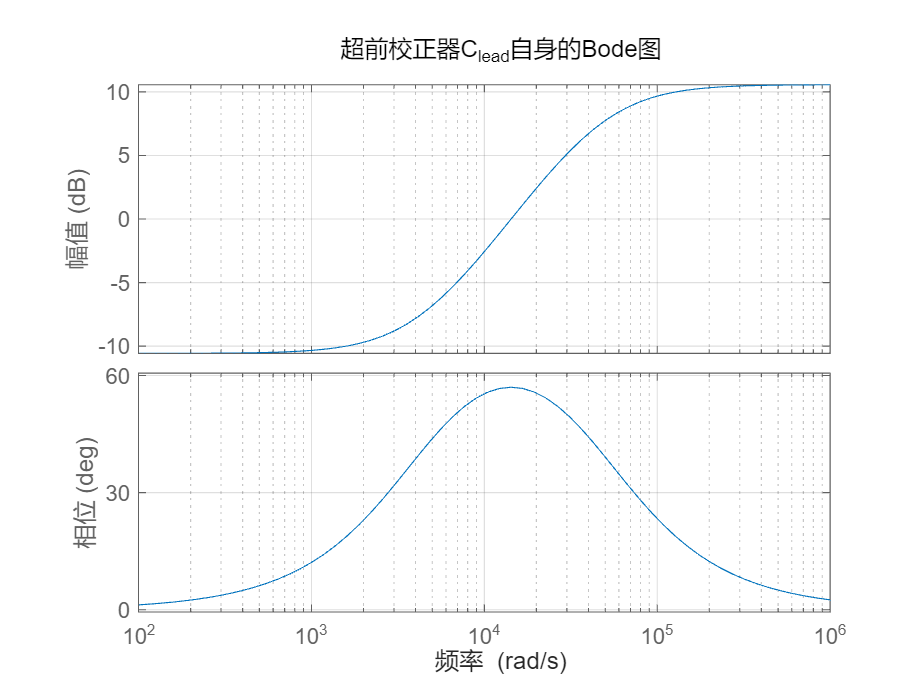


figure;
bode(C_lead);
grid on;
title("超前校正器C_{lead}自身的Bode图");